# Euler-Bernoulli beam (dynamic, 1d)

## Mixed formulation for the simply-supported beam

### DE parameters

% from Lee, D. Wei's paper
L = 1; % length of the beam
rho = 1; % density of the material
E = 1; % young's modulus
sigma_max = .13;
D = -5*(E^2)/(4*sigma_max); % nonlinear elastic modulus
I1 = 1; % moment of inertia
I2 = 0.02; % moment of inertia
% F = 10e6; % external force
F = -2;

f = @(x) F;
hfun = @(x) abs(x).*x;

### FEM parameters

NEL = 50;
gauss_points_num = 3;

master = [0 1];

Nb = 2;
% linear elements
coeffs = [ 0, 1; 
           1,-1];

% basis functions on the master element
N = basis_functions(coeffs);
d1_N = basis_derivatives(coeffs, 1);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

### Matrix assembly

[K,M,Fv] = assemble_system(NEL,Nb,xs,hs,master,N,d1_N,f,gauss_points_num);
Bm = sparse(-M\K);

K1 = sparse(E*I1*K);
K2 = sparse(D*I2*K);
M = sparse(rho*M);

% % for the linear problem
Klen = length(K);

### Solver prep

options = optimset('Display','off');

Tf = 2.5e0;
tau = 2e-2; 
lambda = tau^2;

Ntsteps = round(Tf/tau+1);

Amat = sparse(M-lambda/4*K1*Bm);
Bmat = sparse(2*M+lambda/2*K1*Bm);
Fvec = lambda*Fv;

### Solver routines

us = zeros(Klen,Ntsteps);
ws = zeros(Klen,1);

func1 = @(soln) 2*Amat*soln - (Bmat*us(:,1) + 2*tau*Amat*ws(:) + lambda*K2*hfun(Bm*(soln + us(:,1) - tau*ws(:,1))/2) + Fvec);
us(:,2) = fsolve(func1, ones(Klen,1), options);

for j=3:Ntsteps
    func2 = @(soln) Amat*soln - (Bmat*us(:,j-1) - Amat*us(:,j-2) + lambda*K2*hfun(Bm*(soln + 2*us(:,j-1) + us(:,j-2))/4) + Fvec);
    us(:,j) = fsolve(func2, ones(Klen,1), options);
end

uslin = zeros(Klen,Ntsteps);

uslin(:,2) = (2*Amat)\(Bmat*uslin(:,1) + 2*tau*Amat*(ws(:)) + Fvec);
for j=3:Ntsteps
    uslin(:,j) = Amat\(Bmat*uslin(:,j-1) - Amat*(uslin(:,j-2)) + Fvec);
end

### Solution vectors

us_full = [zeros(1,Ntsteps); us; zeros(1,Ntsteps)];
uslin_full = [zeros(1,Ntsteps); uslin; zeros(1,Ntsteps)];

max(abs(us_full((end-1)/2,:)))

ans = 5.6464e+05

max(abs(uslin_full((end-1)/2,:)))

ans = 0.0521

### Steady-state solutions

Flin_ss = [Fv; zeros(Klen,1)];
Klin_ss = [-K1 zeros(Klen,Klen); M K];

func_ss = @(x) -K1*x - K2*hfun(x) - Fv;

vs_ss = fsolve(func_ss, ones(length(K),1), options);
us_ss = K\(-M*vs_ss);

soln_ss = Klin_ss\Flin_ss;
vslin_ss = soln_ss(1:Klen);
uslin_ss = soln_ss(Klen+1:end);

vs_ss_full = [0;vs_ss;0]; vslin_ss_full = [0;vslin_ss;0];
us_ss_full = [0;us_ss;0]; uslin_ss_full = [0;uslin_ss;0];

## Plotting

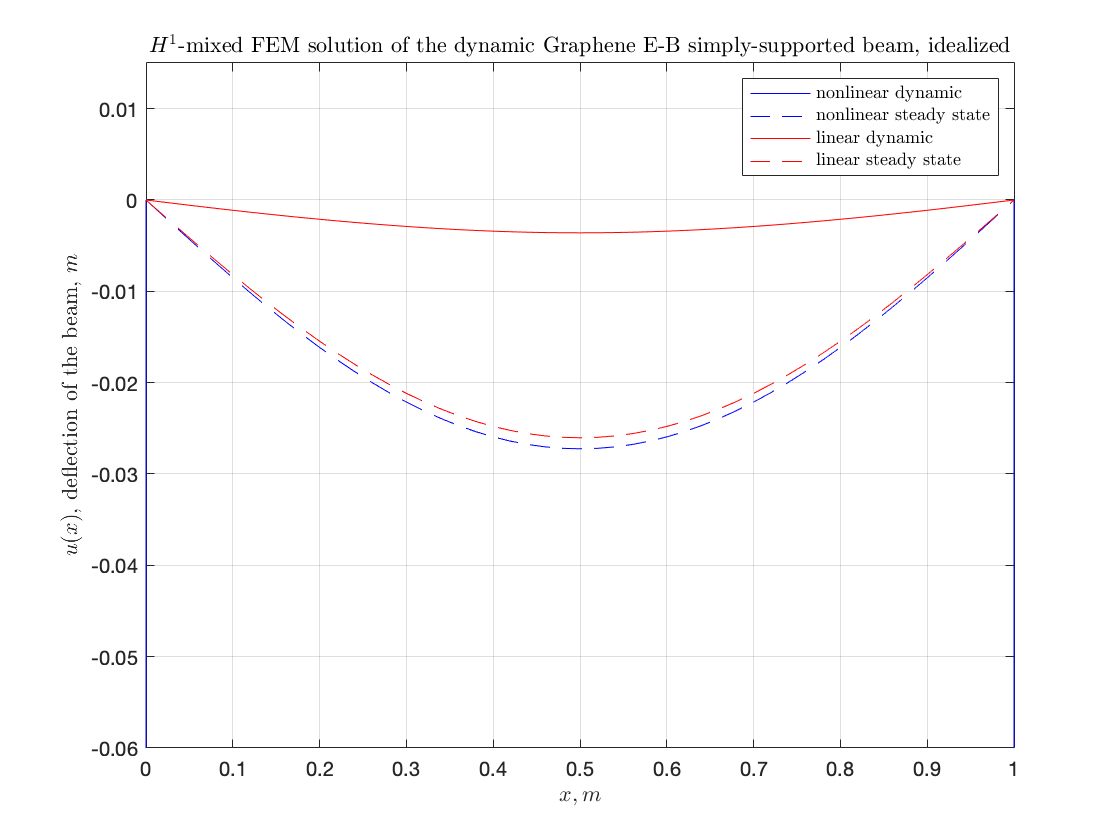

figure
ampl = 6e-2;
for j=1:Ntsteps
    plot(xs,us_full(:,j),'b-', xs,us_ss_full,'b--', xs,uslin_full(:,j),'r-', xs,uslin_ss_full,'r--') 
    
    xlim([0 L])
    ylim([-ampl,ampl/4])
    
    title("$H^1$-mixed FEM solution of the dynamic Graphene E-B simply-supported beam, idealized", "Interpreter","latex")
    
    xlabel('$x, m$', "Interpreter","latex")
    ylabel('$u(x)$, deflection of the beam, $m$', "Interpreter","latex")
    
    leg = legend('nonlinear dynamic', 'nonlinear steady state', 'linear dynamic', 'linear steady state');  
    set(leg,'Interpreter','latex');
    legend("Location","northeast")
    
    grid on
    hold off
    pause(.05)
end

## Appendix

### FEM tools

function [Kmat,Mmat,Fvec] = assemble_system(NEL,Nb,xs,hs,master,N,d1_N,f,gauss_points_num)
    Kl = zeros(Nb,Nb,NEL);
    Ml = zeros(Nb,Nb,NEL);
    Fl = zeros(Nb, 1,NEL);
    for k=1:NEL
        for i=1:Nb
            for j=1:Nb
                Kl(i,j,k) = 1 / (hs(k)) * gauss(@(x) d1_N(i,x) * d1_N(j,x), master(1), master(2), gauss_points_num);
                Ml(i,j,k) =      hs(k)  * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
            end
            % since f is defined globally, we need to apply change of variable to integrate it on the master element
            Fl(i,1,k) =          hs(k)  * gauss(@(x)    N(i,x) * f(xs(k)+hs(k)*x), master(1), master(2), gauss_points_num);
        end
    end
    
    % Global matrices and force term
    Kn = NEL+1;
    K = zeros(Kn,Kn); M = zeros(Kn,Kn);
    F = zeros(Kn,1);
    for i=1:NEL
        K(i:i+1,i:i+1) = K(i:i+1,i:i+1) + Kl(1:Nb,1:Nb,i);
        M(i:i+1,i:i+1) = M(i:i+1,i:i+1) + Ml(1:Nb,1:Nb,i);
        F(i:i+1,1) = F(i:i+1,1) + Fl(1:Nb,1,i);
    end
    
    Kmat = K(2:end-1,2:end-1);
    Mmat = M(2:end-1,2:end-1);
    Fvec = F(2:end-1);
end

### Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end